## 绘制函数图

## **二维**`直角坐标————plot`

### 1.**绘制多个线条**

将 `x` 定义为0到 `2``π` 之间的线性间隔值。将 `y1` 和 `y2` 定义为 `x` 的正弦和余弦值。创建上述两个数据集的线图。

x = 0:0.1:2*pi;
y1 = sin(x);
y2 = cos(x);
plot(x,y1,x,y2)

%% 命令: plot

用法: plot(x,y;s') & plot(x1,y1,s1,x2,y2,s2’,...,xn,yn,sn')

功能:x和y是长度相同的向量,s表示线型和颜色

plot(x1,y1,s1',x2,y2,s2’...,xn,yn,sn'): 作多条曲线在同一图上

一般Sn的代表：

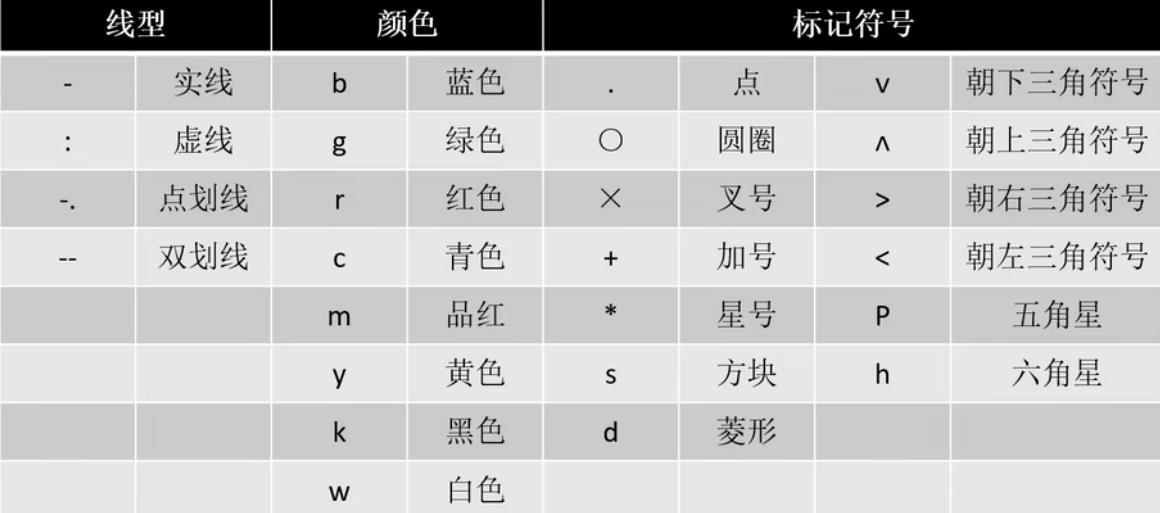

其中线型最常用

2.绘制三条正弦曲线，每条曲线之间存在较小的相移。第一条曲线使用默认的线型。为第二条曲线指定虚线样式，为第三条曲线指定点线样式。

x = 0:pi/100:2*pi;
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
plot(x,y1,x,y2,'--b',x,y3,':r')

### 3.**指定线型、颜色和标记**

绘制三条正弦曲线，每条曲线之间存在较小的相移。第一条正弦曲线使用绿色线条，不带标记。第二条正弦曲线使用蓝色虚线，带圆形标记。第三条正弦曲线只使用青蓝色星号标记。

x = 0:pi/10:2*pi;
y1 = sin(x);
y2 = sin(x-0.25);
y3 = sin(x-0.5);
plot(x,y1,'g',x,y2,'b--o',x,y3,'c*')

### 4.**在特定的数据点显示标记**

通过指定标记符号并将 `MarkerIndices` 属性设置为名称-值对组，**创建一个线图并每隔四个数据点显示一个标记。**

x = linspace(0,10);
y = sin(x);
plot(x,y,'-o','MarkerIndices',1:5:length(y))

### 5.**指定线宽、标记大小和标记颜色**

创建线图并使用 `LineSpec` 选项指定带正方形标记的绿色虚线。使用 `Name,Value` 对组来指定线宽、标记大小和标记颜色。将标记边颜色设置为蓝色，并使用 RGB 颜色值设置标记面颜色。

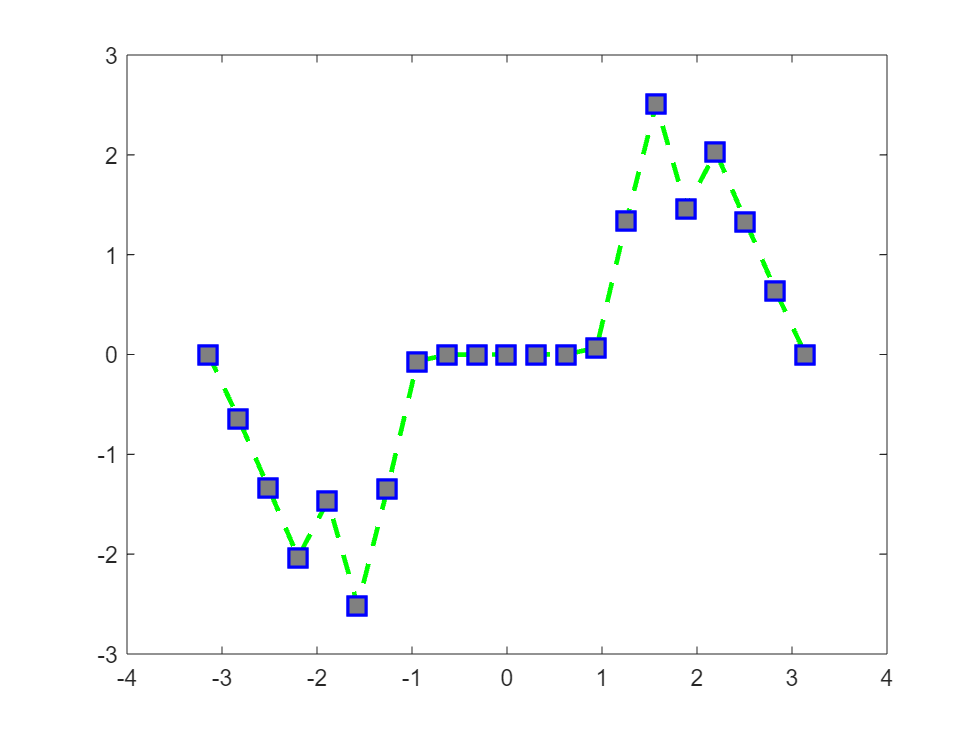

x = -pi:pi/10:pi;
y = tan(sin(x)) - sin(tan(x));
plot(x,y,'--gs',...
    'LineWidth',2,...                 % 线宽 linewidth
    'MarkerSize',10,...               
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])

### 6.**添加标题和轴标签**

使用 `linspace` 函数将 `x` 定义为 0 到 10 之间 150 个值组成的向量。将 `y` 定义为 `x` 的余弦值。

x = linspace(0,10,150);
y = cos(5*x);

创建余弦曲线的二维线图。使用 RGB 颜色值将线条颜色更改为蓝绿色。**使用 **`title`**、**`xlabel`** 和 **`ylabel`** 函数为图形添加标题和轴标签。**

p = plot(x,y,'Color',[0,0.7,0.9])

p =   Line - 属性:

              Color: [0 0.7000 0.9000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0671 0.1342 0.2013 0.2685 0.3356 0.4027 0.4698 0.5369 0.6040 0.6711 0.7383 0.8054 0.8725 0.9396 1.0067 1.0738 1.1409 1.2081 1.2752 1.3423 1.4094 1.4765 1.5436 1.6107 1.6779 1.7450 1.8121 1.8792 1.9463 2.0134 2.0805 2.1477 … ]
              YData: [1 0.9442 0.7831 0.5346 0.2265 -0.1069 -0.4283 -0.7020 -0.8974 -0.9926 -0.9772 -0.8527 -0.6331 -0.3429 -0.0144 0.3157 0.6105 0.8373 0.9706 0.9957 0.9097 0.7222 0.4542 0.1354 -0.1984 -0.5101 -0.7649 -0.9343 -0.9996 -0.9533 -0.8007 … ]

  显示 所有属性


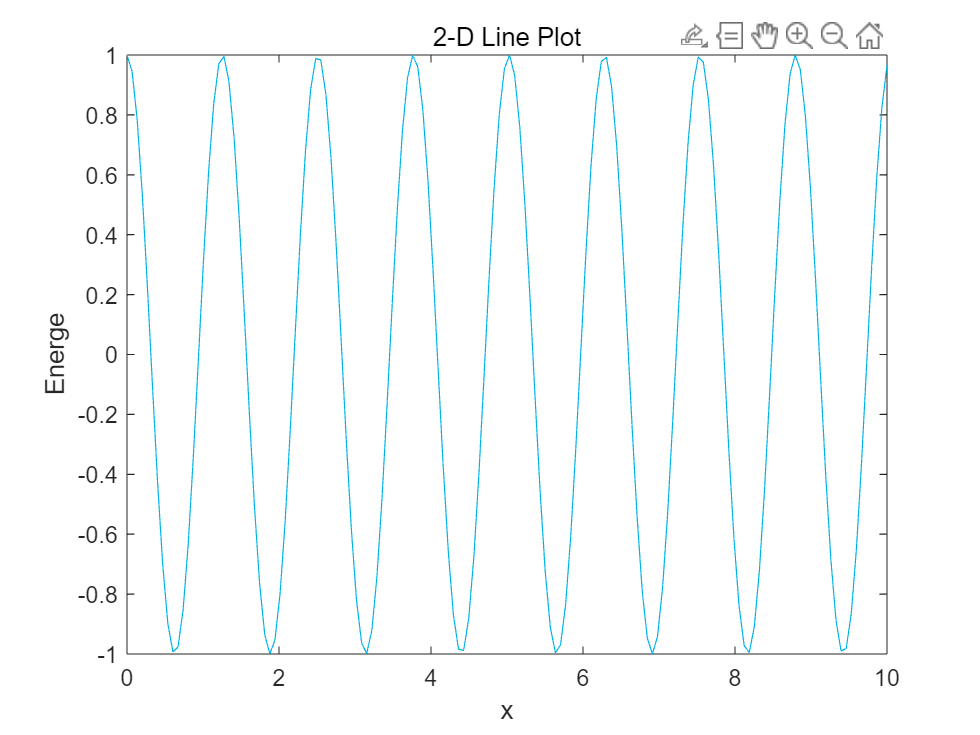

title('2-D Line Plot')
xlabel('x')
ylabel('Energe')   % 此时的x为文本，要带引号

duration(12,45,7)   % 返回的持续时间为 12 小时 45 分钟 7 秒

X = [12 17 54;9 32 3];
D = duration(X)     % 将矩阵转换为持续时间数组

E = duration(1,30:33,0) % 创建一个持续时间数组
F = datetime('today')

### 7.**绘制持续时间并指定刻度格式**

将 `t` 定义为** 7 个介于 0 到 3 分钟之间的 **`duration`** 线性间隔值**。绘制随机数据并使用 `'DurationTickFormat'` 名称-值对组参数指定 `duration` 刻度线的格式。

t = 0:seconds(30):minutes(3);
y = rand(1,7);
plot(t,y,'DurationTickFormat','mm:ss')

### 8.**基于表绘制坐标**

基于表数据绘图的一种便捷方法是将表传递给 `plot` 函数，并指定要绘制的变量。

将 `weather.csv` 作为时间表 `tbl` 读取。然后显示该表的前三行。

tbl = readtimetable("weather.csv");
tbl = sortrows(tbl);
head(tbl,3)

在 x 轴上绘制行时间，在 y 轴上绘制 RainInchesPerMinute 变量。在绘制来自时间表的数据时，默认情况下，行时间绘制在 x 轴上。因此，您不需要指定 Time 变量。以 p 形式返回 Line 对象。请注意，轴标签与变量名称匹配。

p = plot(tbl,"RainInchesPerMinute");

要修改线条的各个方面，请对 Line 对象设置 LineStyle、Color 和 Marker 属性。例如，将线条更改为具有点标记的红色点线。


p.LineStyle = ":";
p.Color = "red";
p.Marker = ".";

doc head

### 9.**在一个轴上绘制多个表变量**

将 `weather.csv` 作为时间表 `tbl` 读取，并显示表的前几行。

tbl = readtimetable("weather.csv");
head(tbl,3)

在 *x* 轴上绘制行时间，在 *y* 轴上绘制 `Temperature` 和 `PressureHg` 变量。在绘制来自时间表的数据时，默认情况下，行时间绘制在 *x* 轴上。因此，您不需要指定 `Time` 变量。

添加一个图例。请注意，图例标签与变量名称匹配。

plot(tbl,["Temperature" "PressureHg"])
legend

### 10.**指定线图的坐标区**

从 R2019b 开始，您可以使用 `tiledlayout` 和 `nexttile` 函数显示分块图。**调用 **`tiledlayout`** 函数以创建一个 2×1 分块图布局**。**调用 **`nexttile`** 函数创建一个坐标区对象，并将该对象返回为 **`ax1`。通过**将 **`ax1`** 传递给 **`plot`** 函数**来创建顶部绘图。通过将坐标区传递给 `title` 和 `ylabel` 函数，为图添加标题和 *y* 轴标签。重复该过程以创建底部绘图。

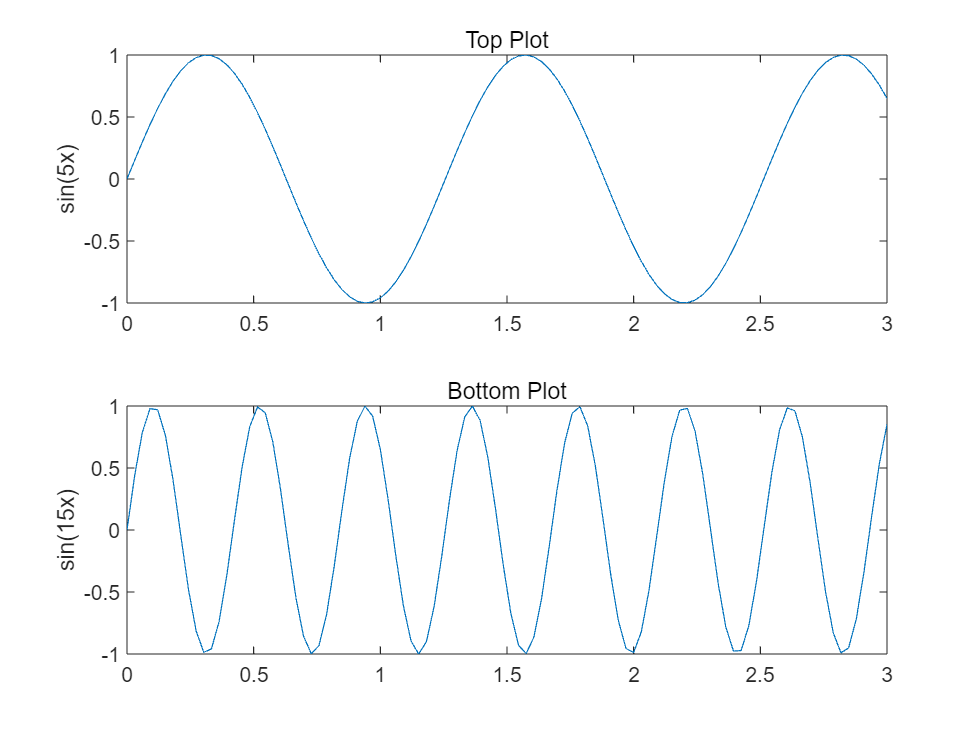

% Create data and 2-by-1 tiled chart layout
x = linspace(0,3);
y1 = sin(5*x);
y2 = sin(15*x);
tiledlayout(2,1)

% Top plot
ax1 = nexttile;
plot(ax1,x,y1)
title(ax1,'Top Plot')
ylabel(ax1,'sin(5x)')

% Bottom plot
ax2 = nexttile;
plot(ax2,x,y2)
title(ax2,'Bottom Plot')
ylabel(ax2,'sin(15x)')

### 11.**创建并修改线条**

将 `x` 定义为 100 个介于 `−``2``π` 和 `2``π` 之间的线性间隔值。将 `y1` 和 `y2` 定义为 `x` 的正弦和余弦值。为上述两个数据集分别创建线图，并在 `p` 中返回两个图形线条。

x = linspace(-2*pi,2*pi);
y1 = sin(x);
y2 = cos(x);
p = plot(x,y1,x,y2);

将第一个线条的**线宽更改为 2。**向第二行添加星形标记。使用圆点表示法设置属性。

p(1).LineWidth = 2;   % 改线宽用 a.linewidth = x
p(2).Marker = '*';

### **12.绘制圆形**

绘制以点 (4,3) 为中心以 2 为半径的圆。**使用 **`axis equal`** 可沿每个坐标方向使用相等的数据单位。**

r = 2;
xc = 4;
yc = 3;

theta = linspace(0,2*pi);
x = r*cos(theta) + xc;
y = r*sin(theta) + yc;
plot(x,y)
axis equal

### 13.多窗口作图

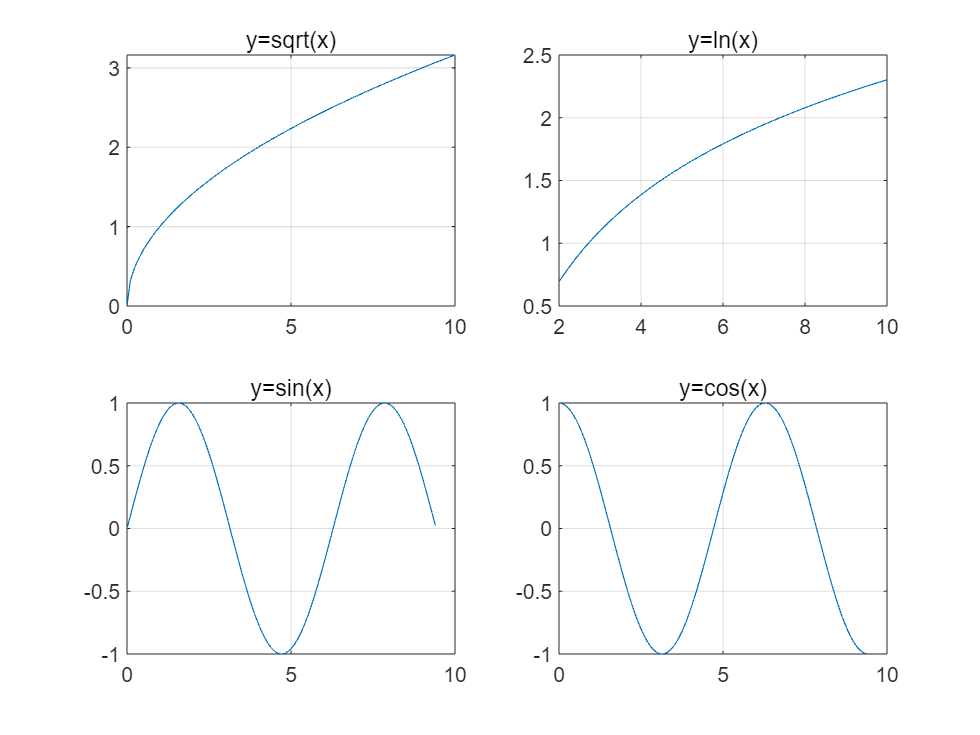

edges 是一个 double 类型的变量。



x1=0:0.1:10;y1=sqrt(x1);
x2=2:0.2:10;y2=log(x2);
x3=0:0.1:3*pi;y3=sin(x3);
x4=0:0.1:3*pi;y4=cos(x4);
subplot(2,2,1);plot(x1,y1);title('y=sqrt(x)');grid on %/ off   显示网格线/取消网格线
subplot(2,2,2);plot(x2,y2);title('y=ln(x)');grid on
subplot(2,2,3);plot(x3,y3);title('y=sin(x)');grid on
subplot(2,2,4);plot(x4,y4);title('y=cos(x)');grid on